The toluene hydrodemethylation reaction is conducted in the gas phase in a PBR reactor:


$$\begin{array}{l}
C_6 H_5 {\mathrm{CH}}_3 +H_2 \to C_6 H_6 +{\mathrm{CH}}_4 \\
T+H_2 \to B+M\\
-{r_1 }^{\prime } =\frac{{\mathrm{kP}}_{H_2 } P_T }{\;1+K_B P_B +K_T P_T }\\
k=8\ldotp 7{\cdot 10}^{-4} \;\left\lbrack \mathrm{mol}\cdot {\mathrm{kg}}^{-1} \cdot {\mathrm{min}}^{-1} \cdot {\mathrm{atm}}^{-2} \right\rbrack ,K_B =1\ldotp 39\;\left\lbrack {\mathrm{atm}}^{-1} \right\rbrack ,K_T =1\ldotp 038\left\lbrack {\mathrm{atm}}^{-1} \right\rbrack 
\end{array}$$


The feed to the reactor is 30 mol% toluene, 45% hydrogen and 25% inerts; excess hydrogen is needed to prevent catalyst build-up. Raw material pressure $P_0 = 40 [atm]$, temperature $T_0 = 640 [C]$. Molar flux of toluene in the raw material, $F_{T_0}  = 50 [mol \cdot  min ^{-1}]$ . Pressure drop parameter $\alpha = 9.8 \times  10^{-5} [kg^{-1}]$.

**Tasks:**

a. Draw a profile of conversion (X), pressure drop (y = P / P0), toluene, hydrogen and benzene partial pressure (PT, PH2, PB) as a function of catalyst weight W = [0, 10,000 kg].

b. Determine for which catalyst mass the pressure will drop to 1 atm.

c. Compare the conversion rate in a PBR containing 10,000 kg of catalyst where there is no pressure drop.

d. Calculate the mass of the catalyst in the fluidized bed reactor with conversion ratio of 0.65; treat it as a CSTR reactor in the calculations.

**Discussion:**

The reaction is of the order of II.

Mechanism of the E-R surface reaction:


$$\begin{array}{l}
C_6 H_5 {\mathrm{CH}}_3 +\Lambda =C_6 H_5 {\mathrm{CH}}_3 ∙\Lambda \\
C_6 H_5 {\mathrm{CH}}_3 ∙\Lambda +H_2 ->C_6 H_6 ∙\Lambda +{\mathrm{CH}}_4 \\
C_6 H_6 ∙\Lambda \to C_6 H_6 +\Lambda 
\end{array}$$



$$\begin{array}{l}
y={{\left(1-\alpha W\right)}}^{0,5} \\
P_T =P_{T_0 } {\left(1-X\right)}y\\
P_{H2} =P_{T_0 } {\left(1.5-X\right)}y\\
P_B =P_{T_0 } \mathrm{Xy}
\end{array}$$


## Task a

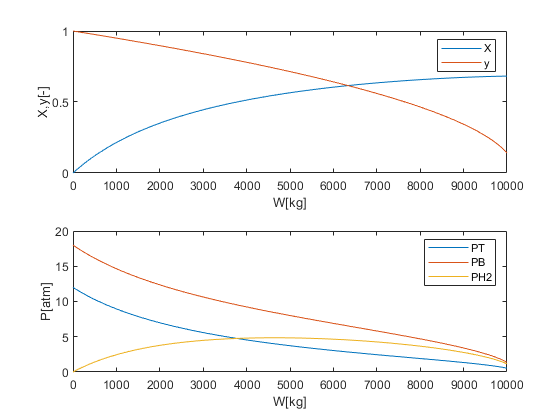

[W,X]=ode45(@Main,[0 1e4],[0]);
 
alfa=9.8e-5;
y=(1-alfa.*W).^(1/2);
PT0=0.3*40;
PT=PT0.*(1-X).*y;
PH2=PT0.*(1.5-X).*y;
PB=PT0.*X.*y;
subplot(2,1,1); plot(W,X,W,y)
legend('X','y')
xlabel('W[kg]')
ylabel('X,y[-]')
subplot(2,1,2); plot(W,PT,W,PH2,W,PB)
legend('PT','PB','PH2')
xlabel('W[kg]')
ylabel('P[atm]')

## Task b


$$y={{\left(1-\alpha W\right)}}^{0,5} \to W=\frac{1-y^2 }{\alpha }=\frac{1-{{\left(\frac{1}{40}\right)}}^2 }{9.8*{10}^{-5} }=10197.7\ \left\lbrack kg\right\rbrack$$


## Task c

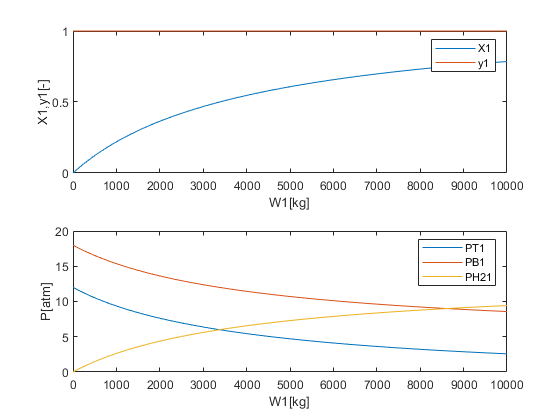

[W1,X1]=ode45(@masa,[0 1e4],[0]);
 
 
alfa=0;
y1=(1-alfa.*W1).^(1/2);
PT0=0.3*40;
PT1=PT0.*(1-X1).*y1;
PH21=PT0.*(1.5-X1).*y1;
PB1=PT0.*X1.*y1;
subplot(2,1,1); plot(W1,X1,W1,y1)
legend('X1','y1')
xlabel('W1[kg]')
ylabel('X1,y1[-]')
subplot(2,1,2); plot(W1,PT1,W1,PH21,W,PB1)
legend('PT1','PB1','PH21')
xlabel('W1[kg]')
ylabel('P[atm]')

## Task d


$$r_T^{\prime } =-\frac{kP_T P_{H2} }{1+K_T P_T +K_B P_B }=-\frac{kP_{T0}^2 *{\left(1-X\right)}*{\left(1.5-X\right)}}{1+K_T P_{T0} *\left(1-X\right)+K_B P_{T0} *X}$$


k=8.7e-4;
X=0.65;
FT0=50;
KB=1.39;
KT=1.038;
PT=PT0*(1-X);
PH2=PT0*(1.5-X);
PB=PT0*X;
PT0=12

PT0 = 12

 
rT2=-((k*PT0^2 *(1-X)*(1.5-X))/(1+KB*PT0*X+KT*PT0*(1-X)))

rT2 = -0.0023

 
W=FT0*X/(-rT2)

W = 1.4128e+04

function dXdW=masa(W1,X1)
FT0=50;
k=8.7e-4;
KB=1.39;
KT=1.038;
alfa=0;
P0=40;
yT0=0.3;
PT0=0.3*40;
y1=(1-alfa*W1)^0.5;
PT1=PT0*(1-X1)*y1;
PH21=PT0*(1.5-X1)*y1;
PB1=PT0*X1*y1;
rT1=-(k*PT1*PH21)/(1+KT*PT1+KB*PB1);
dXdW=[-rT1/FT0];
end
function dXdW=Main(W,X)
FT0=50;
k=8.7e-4;
KB=1.39;
KT=1.038;
alfa=9.8*10^-5;
P0=40;
yT0=0.3;
PT0=0.3*40;
y=(1-alfa*W)^0.5;
PT=PT0*(1-X)*y;
PH2=PT0*(1.5-X)*y;
PB=PT0*X*y;
rT=-(k*PT*PH2)/(1+KT*PT+KB*PB);
dXdW=[-rT/FT0];
end
